clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[3.416;13.058;5.293];
u31=[0.2186;0.9094;0.3539];
r2=[-2.020;4.175;6.921];
u32=[-0.2186;0.9094;-0.3539];
r3=[2.160;4.175;-1.221];
u33=[-0.2186;0.9094;-0.3539];
r4=[9.826;13.058;-1.221];
u34=[-0.2186;0.9094;-0.3539];
r5=[5.646;13.058;6.921];
u35=[-0.2186;0.9094;-0.3539];
r6=[0.070;13.591;2.850];
u36=[-0.2186;-0.9094;-0.3539];
r7=[7.736;4.708;2.850];
u37=[-0.2186;-0.9094;-0.3539];
r8=[3.556;4.708;10.993];
u38=[-0.2186;-0.9094;-0.3539];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];
x8=[];
y8=[];
% center and direction of spheroids

hold on
axis([0 10 0 10]);
for R3=2:1:10 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =    10.3000    2.0000    1.0026


ans =     9.1500    3.0000    1.0035


ans =     7.5000    4.0000    1.0059


ans =     5.6500    5.0000    1.0060


ans =     4.4000    6.0000    1.0086


ans =     3.8000    7.0000    1.0076


ans =     3.5000    8.0000    1.0003


ans =     3.3000    9.0000    1.0029


ans =     3.1500   10.0000    1.0147



values1 = spcrv([[x1(1) x1 x1(end)];[y1(1) y1 y1(end)]],3);
plot(values1(1,:),values1(2,:),'color',[29, 50, 67]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[142, 152, 161]/256, ...
    'DisplayName','1-2');

for R1=2.5:0.5:10 %离心率
    R3=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R3=R3+n;
        R1=R1;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R3=R3-n;
        R1=R1;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =     2.5000   10.0000    1.0054


ans =     3.0000    8.9000    1.0036


ans =     3.5000    7.9500    1.0016


ans =     4.0000    7.1000    1.0066


ans =     4.5000    6.4500    1.0062


ans =     5.0000    5.9500    1.0050


ans =     5.5000    5.5500    1.0052


ans =     6.0000    5.2000    1.0099


ans =     6.5000    4.9500    1.0013


ans =     7.0000    4.6500    1.0099


ans =     7.5000    4.4000    1.0092


ans =     8.0000    4.1500    1.0089


ans =     8.5000    3.9000    1.0076


ans =     9.0000    3.6500    1.0042


ans =     9.5000    3.3500    1.0096


ans =    10.0000    3.1000    1.0002



values2 = spcrv([[x2(1) x2 x2(end)];[y2(1) y2 y2(end)]],3);
plot(values2(1,:),values2(2,:),'color',[221, 42, 22]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[238, 148, 138]/256, ...
    'DisplayName','1-3');

for R3=0:0.5:10 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R3=R3;
        R1=R1+n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R3=R3;
        R1=R1-n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];  
end

ans =     4.5900         0    1.0028


ans =     4.5900    0.5000    1.0026


ans =     4.5900    1.0000    1.0021


ans =     4.5900    1.5000    1.0013


ans =     4.5900    2.0000    1.0002


ans =     4.5800    2.5000    1.0032


ans =     4.5800    3.0000    1.0016


ans =     4.5700    3.5000    1.0041


ans =     4.5700    4.0000    1.0022


ans =     4.5700    4.5000    1.0001


ans =     4.5600    5.0000    1.0022


ans =     4.5600    5.5000    1.0000


ans =     4.5500    6.0000    1.0021


ans =     4.5400    6.5000    1.0042


ans =     4.5400    7.0000    1.0020


ans =     4.5300    7.5000    1.0042


ans =     4.5300    8.0000    1.0021


ans =     4.5300    8.5000    1.0000


ans =     4.5200    9.0000    1.0024


ans =     4.5200    9.5000    1.0005


ans =     4.5100   10.0000    1.0031



values3 = spcrv([[x3(1) x3 x3(end)];[y3(1) y3 y3(end)]],3);
plot(values3(1,:),values3(2,:),'color',[191, 144, 0]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[223, 199, 127]/256, ...
    'DisplayName','1-4');

for R3=1:0.5:10 %离心率
    R1=1;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];  
end

ans =     1.4300    1.0000    1.0095


ans =     1.3500    1.5000    1.0107


ans =     1.2400    2.0000    1.0088


ans =     1.1000    2.5000    1.0092


ans = 1×3
    0.9500    3.0000    1.0101


ans = 1×3
    0.8300    3.5000    1.0014


ans = 1×3
    0.7400    4.0000    1.0026


ans = 1×3
    0.6800    4.5000    1.0070


ans = 1×3
    0.6400    5.0000    1.0124


ans = 1×3
    0.6100    5.5000    1.0236


ans = 1×3
    0.6000    6.0000    1.0035


ans = 1×3
    0.5800    6.5000    1.0213


ans = 1×3
    0.5700    7.0000    1.0213


ans = 1×3
    0.5600    7.5000    1.0281


ans = 1×3
    0.5600    8.0000    1.0087


ans = 1×3
    0.5500    8.5000    1.0244


ans = 1×3
    0.5500    9.0000    1.0108


ans = 1×3
    0.5400    9.5000    1.0328


ans = 1×3
    0.5400   10.0000    1.0229



values4 = spcrv([[x4(1) x4 x4(end)];[y4(1) y4 y4(end)]],3);
plot(values4(1,:),values4(2,:),'color',[56, 87, 35]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-5');

for R3=0.57:0.1:10 %离心率
    R1=2;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];  
end

ans = 1×3
    9.5400    0.5700    1.0001


ans = 1×3
    3.6000    0.6700    1.0009


ans = 1×3
    2.9000    0.7700    1.0028


ans = 1×3
    2.6100    0.8700    1.0030


ans = 1×3
    2.4500    0.9700    1.0034


ans = 1×3
    2.3500    1.0700    1.0036


ans = 1×3
    2.2800    1.1700    1.0053


ans = 1×3
    2.2300    1.2700    1.0065


ans = 1×3
    2.2000    1.3700    1.0020


ans = 1×3
    2.1700    1.4700    1.0036


ans = 1×3
    2.1500    1.5700    1.0021


ans = 1×3
    2.1300    1.6700    1.0041


ans = 1×3
    2.1200    1.7700    1.0004


ans = 1×3
    2.1000    1.8700    1.0074


ans = 1×3
    2.0900    1.9700    1.0075


ans = 1×3
    2.0800    2.0700    1.0089


ans = 1×3
    2.0800    2.1700    1.0024


ans = 1×3
    2.0700    2.2700    1.0059


ans = 1×3
    2.0700    2.3700    1.0009


ans = 1×3
    2.0600    2.4700    1.0058


ans = 1×3
    2.0600    2.5700    1.0019


ans = 1×3
    2.0500    2.6700    1.0078


ans = 1×3
    2.0500    2.7700    1.0047


ans = 1×3
    2.0500    2.8700    1.0020


ans = 1×3
    2.0400    2.9700    1.0090


ans = 1×3
    2.0400    3.0700    1.0067


ans = 1×3
    2.0400    3.1700    1.0047


ans = 1×3
    2.0400    3.2700    1.0028


ans = 1×3
    2.0400    3.3700    1.0012


ans = 1×3
    2.0300    3.4700    1.0092


ans = 1×3
    2.0300    3.5700    1.0078


ans = 1×3
    2.0300    3.6700    1.0065


ans = 1×3
    2.0300    3.7700    1.0053


ans = 1×3
    2.0300    3.8700    1.0042


ans = 1×3
    2.0300    3.9700    1.0032


ans = 1×3
    2.0300    4.0700    1.0022


ans = 1×3
    2.0300    4.1700    1.0013


ans = 1×3
    2.0300    4.2700    1.0005


ans = 1×3
    2.0200    4.3700    1.0095


ans = 1×3
    2.0200    4.4700    1.0088


ans = 1×3
    2.0200    4.5700    1.0081


ans = 1×3
    2.0200    4.6700    1.0075


ans = 1×3
    2.0200    4.7700    1.0069


ans = 1×3
    2.0200    4.8700    1.0064


ans = 1×3
    2.0200    4.9700    1.0059


ans = 1×3
    2.0200    5.0700    1.0054


ans = 1×3
    2.0200    5.1700    1.0049


ans = 1×3
    2.0200    5.2700    1.0045


ans = 1×3
    2.0200    5.3700    1.0041


ans = 1×3
    2.0200    5.4700    1.0037


ans = 1×3
    2.0200    5.5700    1.0033


ans = 1×3
    2.0200    5.6700    1.0030


ans = 1×3
    2.0200    5.7700    1.0026


ans = 1×3
    2.0200    5.8700    1.0023


ans = 1×3
    2.0200    5.9700    1.0020


ans = 1×3
    2.0200    6.0700    1.0017


ans = 1×3
    2.0200    6.1700    1.0015


ans = 1×3
    2.0200    6.2700    1.0012


ans = 1×3
    2.0200    6.3700    1.0010


ans = 1×3
    2.0200    6.4700    1.0007


ans = 1×3
    2.0200    6.5700    1.0005


ans = 1×3
    2.0200    6.6700    1.0003


ans = 1×3
    2.0200    6.7700    1.0001


ans = 1×3
    2.0100    6.8700    1.0098


ans = 1×3
    2.0100    6.9700    1.0096


ans = 1×3
    2.0100    7.0700    1.0094


ans = 1×3
    2.0100    7.1700    1.0093


ans = 1×3
    2.0100    7.2700    1.0091


ans = 1×3
    2.0100    7.3700    1.0089


ans = 1×3
    2.0100    7.4700    1.0088


ans = 1×3
    2.0100    7.5700    1.0086


ans = 1×3
    2.0100    7.6700    1.0085


ans = 1×3
    2.0100    7.7700    1.0084


ans = 1×3
    2.0100    7.8700    1.0082


ans = 1×3
    2.0100    7.9700    1.0081


ans = 1×3
    2.0100    8.0700    1.0080


ans = 1×3
    2.0100    8.1700    1.0079


ans = 1×3
    2.0100    8.2700    1.0078


ans = 1×3
    2.0100    8.3700    1.0077


ans = 1×3
    2.0100    8.4700    1.0076


ans = 1×3
    2.0100    8.5700    1.0075


ans = 1×3
    2.0100    8.6700    1.0074


ans = 1×3
    2.0100    8.7700    1.0073


ans = 1×3
    2.0100    8.8700    1.0072


ans = 1×3
    2.0100    8.9700    1.0071


ans = 1×3
    2.0100    9.0700    1.0070


ans = 1×3
    2.0100    9.1700    1.0069


ans = 1×3
    2.0100    9.2700    1.0069


ans = 1×3
    2.0100    9.3700    1.0068


ans = 1×3
    2.0100    9.4700    1.0067


ans = 1×3
    2.0100    9.5700    1.0066


ans = 1×3
    2.0100    9.6700    1.0066


ans = 1×3
    2.0100    9.7700    1.0065


ans = 1×3
    2.0100    9.8700    1.0064


ans = 1×3
    2.0100    9.9700    1.0064



values5 = spcrv([[x5(1) x5 x5(end)];[y5(1) y5 y5(end)]],3);
plot(values5(1,:),values5(2,:),'color',[63, 125, 162]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[159, 190, 208]/256, ...
    'DisplayName','1-6');

for R3=3.9:0.2:10 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r7,R1,R3,u31,u37);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R3=R3;
        R1=R1+n;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    
    while miu2<1
        R3=R3;
        R1=R1-n;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    [R1,R3,miu2]
    x6=[x6,R1];
    y6=[y6,R3];  
end

ans = 1×3
   11.4700    3.9000    1.0001


ans = 1×3
    7.6800    4.1000    1.0003


ans = 1×3
    6.3200    4.3000    1.0005


ans = 1×3
    5.5900    4.5000    1.0002


ans = 1×3
    5.1200    4.7000    1.0003


ans = 1×3
    4.7900    4.9000    1.0008


ans = 1×3
    4.5500    5.1000    1.0003


ans = 1×3
    4.3600    5.3000    1.0009


ans = 1×3
    4.2100    5.5000    1.0011


ans = 1×3
    4.0900    5.7000    1.0008


ans = 1×3
    3.9900    5.9000    1.0006


ans = 1×3
    3.9000    6.1000    1.0022


ans = 1×3
    3.8300    6.3000    1.0015


ans = 1×3
    3.7700    6.5000    1.0007


ans = 1×3
    3.7100    6.7000    1.0028


ans = 1×3
    3.6600    6.9000    1.0037


ans = 1×3
    3.6200    7.1000    1.0030


ans = 1×3
    3.5800    7.3000    1.0041


ans = 1×3
    3.5500    7.5000    1.0027


ans = 1×3
    3.5200    7.7000    1.0027


ans = 1×3
    3.4900    7.9000    1.0040


ans = 1×3
    3.4700    8.1000    1.0020


ans = 1×3
    3.4500    8.3000    1.0009


ans = 1×3
    3.4300    8.5000    1.0007


ans = 1×3
    3.4100    8.7000    1.0013


ans = 1×3
    3.3900    8.9000    1.0026


ans = 1×3
    3.3700    9.1000    1.0047


ans = 1×3
    3.3600    9.3000    1.0024


ans = 1×3
    3.3500    9.5000    1.0006


ans = 1×3
    3.3300    9.7000    1.0044


ans = 1×3
    3.3200    9.9000    1.0036



values6 = spcrv([[x6(1) x6 x6(end)];[y6(1) y6 y6(end)]],3);
plot(values6(1,:),values6(2,:),'color',[237, 125, 49]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[237, 125, 49]/256, ...
    'DisplayName','1-7');

for R3=3:0.5:10 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r8,R1,R3,u31,u38);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R3=R3;
        R1=R1+n;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    
    while miu2<1
        R3=R3;
        R1=R1-n;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    [R1,R3,miu2]
    x7=[x7,R1];
    y7=[y7,R3];  
end

ans = 1×3
   11.0800    3.0000    1.0000


ans = 1×3
    6.9200    3.5000    1.0008


ans = 1×3
    5.8600    4.0000    1.0009


ans = 1×3
    5.3600    4.5000    1.0017


ans = 1×3
    5.0700    5.0000    1.0027


ans = 1×3
    4.8900    5.5000    1.0015


ans = 1×3
    4.7600    6.0000    1.0022


ans = 1×3
    4.6700    6.5000    1.0013


ans = 1×3
    4.6000    7.0000    1.0014


ans = 1×3
    4.5400    7.5000    1.0036


ans = 1×3
    4.5000    8.0000    1.0026


ans = 1×3
    4.4700    8.5000    1.0007


ans = 1×3
    4.4400    9.0000    1.0014


ans = 1×3
    4.4100    9.5000    1.0040


ans = 1×3
    4.3900   10.0000    1.0041



values7 = spcrv([[x7(1) x7 x7(end)];[y7(1) y7 y7(end)]],3);
plot(values7(1,:),values7(2,:),'color',[151, 150, 159]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[151, 150, 159]/256, ...
    'DisplayName','1-8');


for R3=1.1:0.2:10 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r3,R1,R3,u32,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R3=R3;
        R1=R1+n;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    
    while miu2<1
        R3=R3;
        R1=R1-n;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    [R1,R3,miu2]
    x8=[x8,R1];
    y8=[y8,R3];  
end

ans = 1×3
   10.0200    1.1000    1.0002


ans = 1×3
    6.8300    1.3000    1.0012


ans = 1×3
    5.9200    1.5000    1.0002


ans = 1×3
    5.4800    1.7000    1.0001


ans = 1×3
    5.2200    1.9000    1.0012


ans = 1×3
    5.0500    2.1000    1.0027


ans = 1×3
    4.9400    2.3000    1.0014


ans = 1×3
    4.8600    2.5000    1.0005


ans = 1×3
    4.7900    2.7000    1.0033


ans = 1×3
    4.7500    2.9000    1.0003


ans = 1×3
    4.7100    3.1000    1.0011


ans = 1×3
    4.6800    3.3000    1.0008


ans = 1×3
    4.6500    3.5000    1.0027


ans = 1×3
    4.6300    3.7000    1.0024


ans = 1×3
    4.6100    3.9000    1.0035


ans = 1×3
    4.6000    4.1000    1.0015


ans = 1×3
    4.5900    4.3000    1.0004


ans = 1×3
    4.5700    4.5000    1.0041


ans = 1×3
    4.5700    4.7000    1.0002


ans = 1×3
    4.5600    4.9000    1.0009


ans = 1×3
    4.5500    5.1000    1.0020


ans = 1×3
    4.5400    5.3000    1.0035


ans = 1×3
    4.5400    5.5000    1.0010


ans = 1×3
    4.5300    5.7000    1.0031


ans = 1×3
    4.5300    5.9000    1.0011


ans = 1×3
    4.5200    6.1000    1.0036


ans = 1×3
    4.5200    6.3000    1.0020


ans = 1×3
    4.5200    6.5000    1.0005


ans = 1×3
    4.5100    6.7000    1.0035


ans = 1×3
    4.5100    6.9000    1.0023


ans = 1×3
    4.5100    7.1000    1.0012


ans = 1×3
    4.5100    7.3000    1.0001


ans = 1×3
    4.5000    7.5000    1.0035


ans = 1×3
    4.5000    7.7000    1.0027


ans = 1×3
    4.5000    7.9000    1.0018


ans = 1×3
    4.5000    8.1000    1.0011


ans = 1×3
    4.5000    8.3000    1.0004


ans = 1×3
    4.4900    8.5000    1.0041


ans = 1×3
    4.4900    8.7000    1.0035


ans = 1×3
    4.4900    8.9000    1.0029


ans = 1×3
    4.4900    9.1000    1.0024


ans = 1×3
    4.4900    9.3000    1.0019


ans = 1×3
    4.4900    9.5000    1.0015


ans = 1×3
    4.4900    9.7000    1.0010


ans = 1×3
    4.4900    9.9000    1.0006


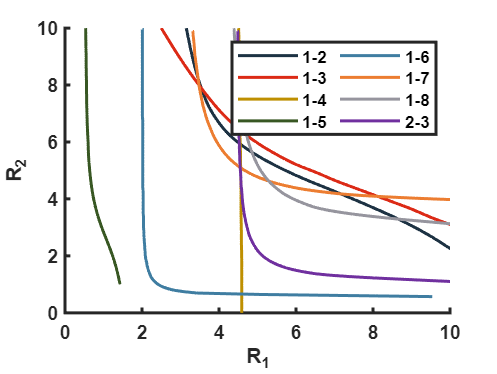


values8 = spcrv([[x8(1) x8 x8(end)];[y8(1) y8 y8(end)]],3);
plot(values8(1,:),values8(2,:),'color',[112, 48, 160]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[112, 48, 160]/256, ...
    'DisplayName','2-3');


set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_2','FontName','arial','FontWeight','bold');
legend('Location','northeast','NumColumns',2);
hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end



